# Exercise 4: Swingarm Optimization for Strength using MATLAB and `PythonOCC`

**Introduction**

Manual changes of the geometry and reevaluation of the strength for the given load cases can be quite tedious. Therefore, it is recommended to use established optimization routines such that the ones provided by the [Optimization Toolbox](https://www.mathworks.com/products/optimization.html)™ and the [Global Optimization Toolbox](https://www.mathworks.com/products/global-optimization.html)™. In this exercise you will learn how to define an appropriate cost function, define an appropriate constraint for the well-posedeness of the optimization problem at hand, and use the [Optimize Live Task](https://www.mathworks.com/help/matlab/math/optimize-live-editor-matlab.html) in MATLAB to perform optimization of the motorcycle swingarm for strength. 

**To interact with this Exercise: **

**Whenever you see the icon ** , **this will indicate the specific steps you should take to complete the section of the exercise. **Also, instead of executing the whole script, run each section separately (see below) or using the keyboard shortcut (`Ctrl+Enter`): 

 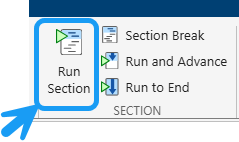 

## 1) Setup `PythonOCC` environment

**Instructions**

In this first step, you will load the python environment that contains all needed functions to use PythonOCC from MATLAB. If this is the first time you run this section, the installation of `PythonOCC` may take up to approximately one minute. Otherwise, it will take just a few seconds to create the new geometry representation used in the exercise. 

**Load the **`PythonOCC`** environment and install custom functions**

clear, geometryFunctions = env_conf(true);

**Setup geometry **`PythonOCC`** object**

fileName = fullfile(".", "geometry", "swingarm brep.igs");
geometryObj = geometryFunctions.MyApp();
geometryObj.readGeometryFile(fileName)

  Run this section of code by using "Run Section" in the toolstrip or clicking the "Run Code Section" button below:

## 2) Select Edge for Update

Using `PythonOCC `you can select any edges or control points to start modifying the geometry. To limit choices during this workshop, you will have a subset of 3 edges to choose from. Use the dropdown list in the code below to select the edge of the geometry you would like to update (use the screenshots below as reference for the three different edges that can be modified) 

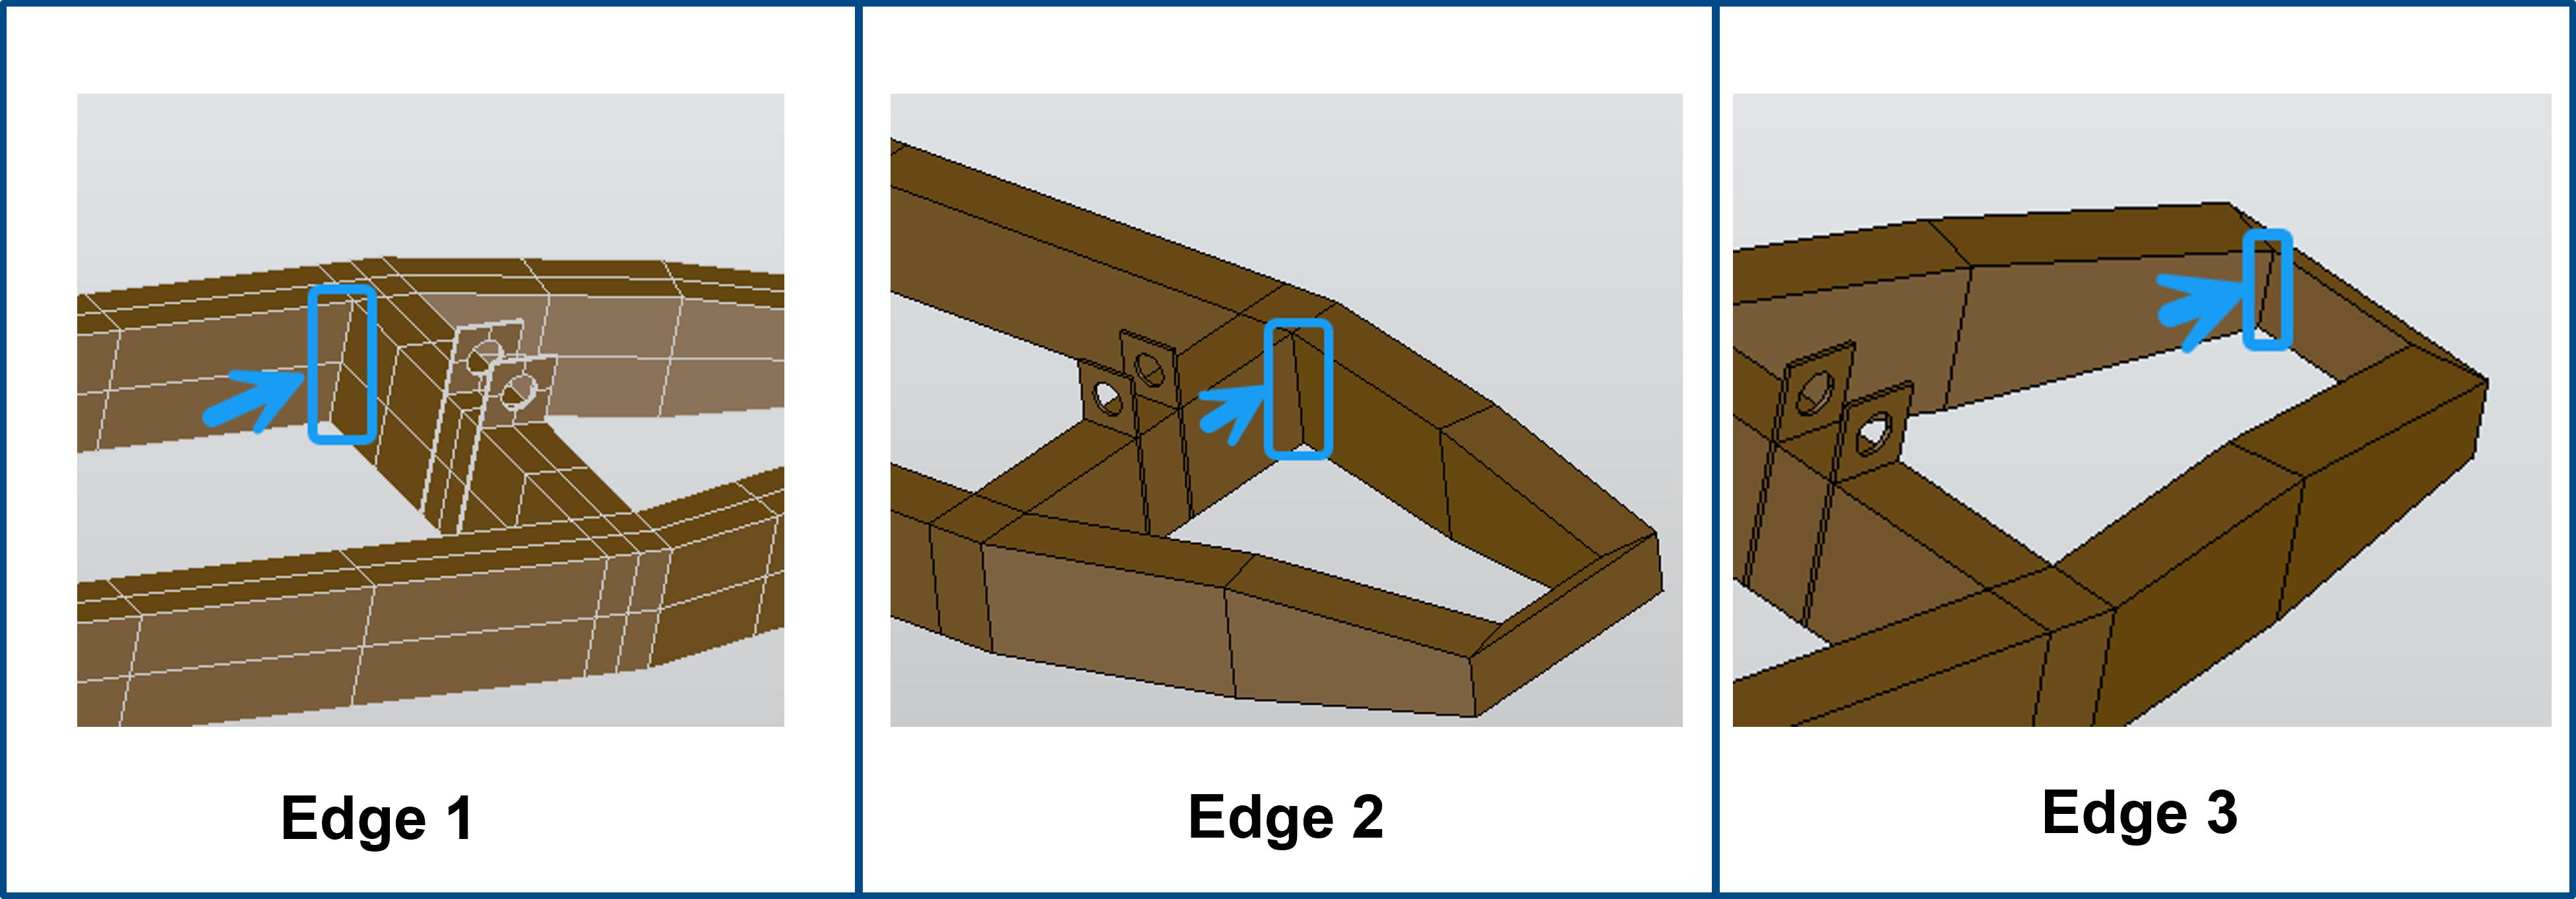

  Select an element from the dropdown list below. Note this Section will run automatically once you make a selection.

edgeID = 34;
geometryObj.selectedEdges = py.list([]);
selectedEdge = getSelectedEdge(geometryObj.baseShape, edgeID);
geometryObj.selectedEdges.append(selectedEdge)
geometryObj.getDataDesignVariables(py.int(0))
geometryObj.computeNumDesignVariables()
displaySelection(edgeID)

## 3) Select an Initial Guess for the Design Update

**Instructions**

- Please choose a value between -100 and 100 for the edit field here (the units are cm)

- This value will be used as a starting point for the optimization algorithm in Section 4.) Perform Swingarm Optimization and it plays a crucial role in the optimization process

(This Code Section will run automatically once you move the value of this edit field has been entered)

  Choose a value between -100 and 100 for `d0` (the units are cm). Note this Section will run automatically once you make a selection.

d0 = 0; % [cm]
if d0 < -100 || d0 > 100
    error("Please select a value for the initial guess of the design update between -100 and 100. You chose %d", d0)
end

Inline definition of the cost and the nonlinear constraint function

STEPFileName = fullfile(".", "metadata", "swingarm brep updated.step");
myComputeStrainEnergy = @(d) computeStrainEnergy(d, geometryFunctions, geometryObj, STEPFileName, true);
myAngleConstraint = @(d) computeAngleConstraint(d, geometryObj);

## 4) Perform Swingarm Optimization

  **Instructions**

- Note that the initial guess selected in Section 3.) Select an Initial Guess for the Design Update is used in the Optimize Live Task below: 

- The [Optimization Toolbox™](https://www.mathworks.com/products/optimization.html) and the [Global Optimization Toolbox™](https://www.mathworks.com/products/global-optimization.html) offer a plethora of functions that can be used for optimization. This problem involves a nonlinear cost function with a nonlinear constraint. The cost function is the strain energy which is sought to be minimized for a stronger design: . The assumed nonlinear constraint herein is, that the angle of the faces adjacent to the selected edges must not become negative: . This makes sense because we do not want our final design to have a sharp kink in any of the optimized corners! For this problem, please use the already selected Patter Search algorithm for the optimization, see  

- Run this Code Section by clicking the "Run" button below. Observe how the design changes throughout the iterations in the output section right under the Optimize Live Task. Let the optimizer conclude and play the automatically generated animation showing how the design changes through the optimization iterations

% Set nondefault solver options
options = optimoptions("patternsearch","MaxIterations",2,"MaxTime",60);

% Solve
[solution,objectiveValue] = patternsearch(myComputeStrainEnergy,d0,[],[],[],...
    [],zeros(size(d0)),[],myAngleConstraint,options);

% Clear variables
clearvars options

- If you want to know more about how the cost function is formulated, please navigate to auxiliary function [`computeStrainEnergy.mlx`](matlab:open('./auxiliary functions/computeStrainEnergy.mlx'))

- If you want to know more about how the constraint function is formulated, please navigate to auxiliary function [`computeAngleConstraint.mlx`](matlab:open('./auxiliary functions/computeAngleConstraint.mlx'))

## 5) Assess the Optimization Results

  **Instructions**

- Please make sure that the optimization from Section 4.) Perform Swingarm Optimization has concluded and that variable `solution` exists in the workspace

- Run this Code Section using the "Run" button below

- Rotate the embedded figure and observe the optimal swingarm design achieved by the optimizer. What is your observation?

- Observe the strain energy for the optimal swingarm design achieved by the optimizer displayed here. How does this compare to the value strain energy for the original model [here](matlab:open('./main_Exercise2.mlx'))? Why?

- What can you say about the angle between the adjacent faces of the selected edge displayed here (in degrees °)? What do you think was the original angle between the adjacent to the selected edge faces?

**Visualize the updated design**

geometryObj.updateShape(py.list(num2cell(solution)));
gm = importGeometry(STEPFileName);
pdegplot(gm, EdgeLabels="off", FaceLabels="off", FaceAlpha=0.5)

**Compute the strain energy at the optimal design**

geometryObj.updateShape(py.list(num2cell(solution)))
pyTuple = geometryFunctions.createSolidFromBRepCompound(geometryObj.updatedShape);
geometryFunctions.writeGeometryToFile(STEPFileName, pyTuple{1})
strainEnergy = computeStrainEnergy(solution, geometryFunctions, geometryObj, STEPFileName, false);
disp("The strain energy at the optimal swingarm design is equal to: " + strainEnergy)

**Compute the angle between the adjacent to the selected edge faces at the optimal design**

theta = computeAngleConstraint(solution, geometryObj);
disp("The angle between the adjacent to the selected edge faces at the optimal design is equal to: " + theta)


**When you complete Exercise 4:**

**Continue to **[**Example 5**](matlab:open('./Example5.mlx'))** or back to **[**README**](matlab:open('./README.mlx'))

*Copyright 2024 The MathWorks, Inc.*